# **IO291 LowSide - Digital LVTTL and FET Loopback**

This example shows you how to perform a loopback test with the IO291 LowSide I/O module to verify the LVTTL and FET digital loopback functionality of some of the input and output channels.

The IO291 is a digital module providing eight optically isolated non-polarized inputs with up to 48 VDC, eight fully protected FET output switches with 5 to 48 VDC at up to 0.5 A (LowSide), and eight LVTTL I/O channels programmable as inputs or outputs in groups of 4 lines.

The Simulink model features the [IO291 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_setup), [IO291 LVTTL digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_lvttl_digital_input), [IO291 LVTTL digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_lvttl_digital_output), [IO291 FET digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_fet_digital_output), and [IO291 Isolated digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_isolated_digital_input) blocks.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO291 LowSide I/O module installed

- Connector cable from the I/O module to the terminal board

- 1 x 2-way 17-pin M12 terminal board with jumper wires

- External DC power supply

- Load resistor

### Loopback Wiring

This example can be used as a loopback test, where the LVTTL and FET Digital Outputs are wired back to the LVTTL and FET Digital Inputs. Select the correct load resistor value according to the DC power supply and the maximum current (0.5 A). 

The following wiring is required:

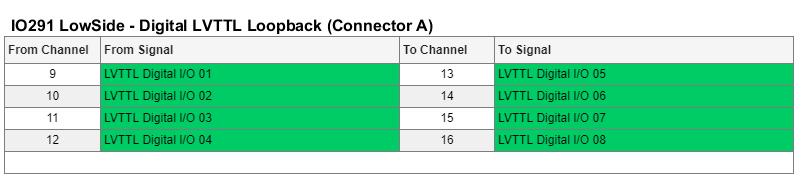

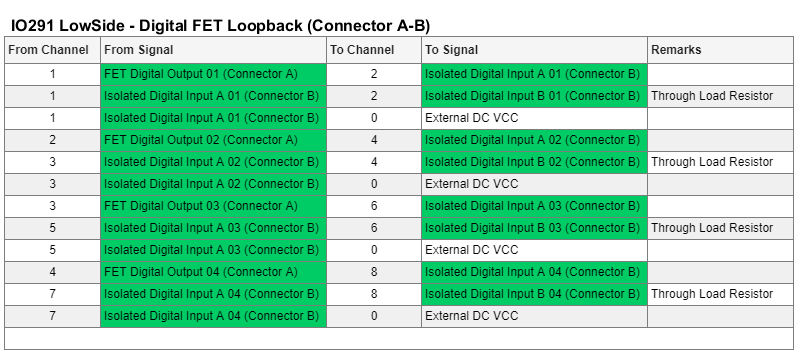

The full pin mapping of the IO291 can be found here: [IO291 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io291_pin_mapping)

## Open Simulink Model

 
modelName = 'sgMdl_IO291_LS_DigitalLoopback';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the two Simulink scopes connected to the LVTTL and FET Digital input blocks and compare the signals to check if the loopback is working as expected. On the LVTTL and FET Scope, four pulses must be displayed:

**Scope for LVTTL Digital Inputs**

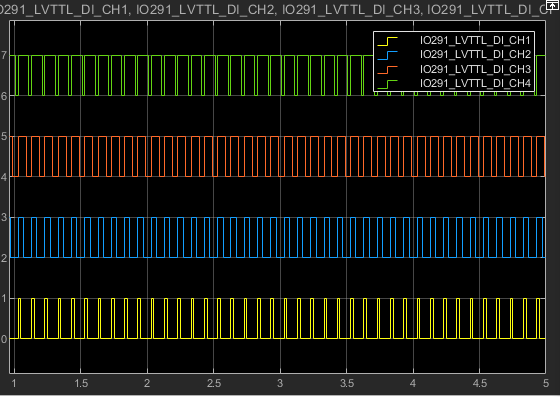

 **Scope for FET Digital Inputs**

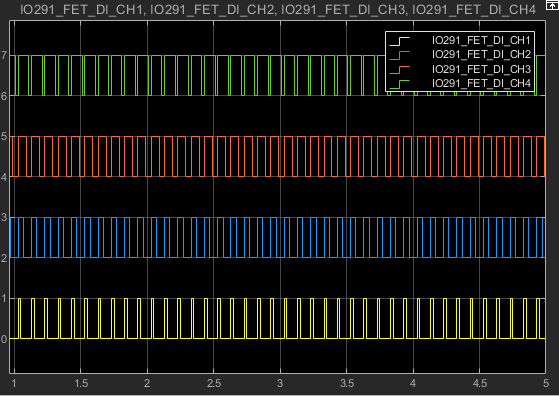

## Additional References

- [IO291 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io291)